Consider a chain of pendulums attached to a slider as follows

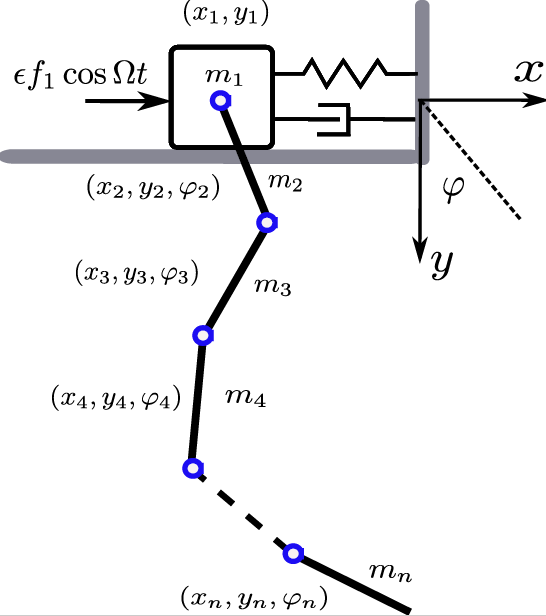

Here we set $n=41$ and construct two-dimensional SSM-based reduced-order model.

We rescale V and W such that the coefficients of reduced dynamics are not tiny. Note that we found that the results at physical coordiantes are not affected by the rescaling here due to the dual relation of reduced dynamics and SSM expansion map.

clear all

## Setup model

m1 = 0.61;
m  = 0.02;
c1 = 0.22;% 0.02;
c  = 0.06;
k1 = 6.5;
k  = 4.1;
n  = 41;
len = 0.03;

[A,B,Fnl,Fext] = build_model(m1,m,c1,c,k1,k,len,n);

DS = DynamicalSystem();
set(DS,'B',B,'A',A,'fnl',Fnl);
set(DS.Options,'Nmax',4,'notation','multiindex')

**Linear Modal analysis**

set(DS.Options, 'sigma', 2);
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
  -0.0569 + 1.9939i
  -0.0569 - 1.9939i
  -0.0730 + 4.9038i
  -0.0730 - 4.9038i



% Rescale V and W such that the coefficients of reduced dynamics are not
% tiny. Note that we found that the results at physical coordiantes are not
% affected by the rescaling here due to the dual relation of reduced
% dynamics and SSM expansion map.
scale_factor = 10;
DS.spectrum.V = V*scale_factor;
DS.spectrum.W = W/scale_factor;

## Autonomous SSM 

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
order = 13;             % SSM expansion order
S.choose_E(resonant_modes)

sigma_out = 1
sigma_in = 1


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.67E+00 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.82E+00 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.98E+00 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.26E+00 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.59E+00 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 4.05E+00 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 4.59E+00 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 5.29E+00 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 6.09E+00 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 7.06E+00 MB
Manifold computation time 

#### Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} -0.001757\,{\rho_{1}}^{13}+0.001242\,{\rho_{1}}^{11}-0.0009862\,{\rho_{1}}^{9}+0.000832\,{\rho_{1}}^{7}+0.0001677\,{\rho_{1}}^{5}-0.004259\,{\rho_{1}}^{3}-0.05691\,\rho_{1}\\ 0.004065\,{\rho_{1}}^{12}-0.002778\,{\rho_{1}}^{10}+0.002133\,{\rho_{1}}^{8}+0.0003925\,{\rho_{1}}^{6}-0.0107\,{\rho_{1}}^{4}+0.04249\,{\rho_{1}}^{2}+1.994 \end{array}\right)$$

Convergence of backbone curve

syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

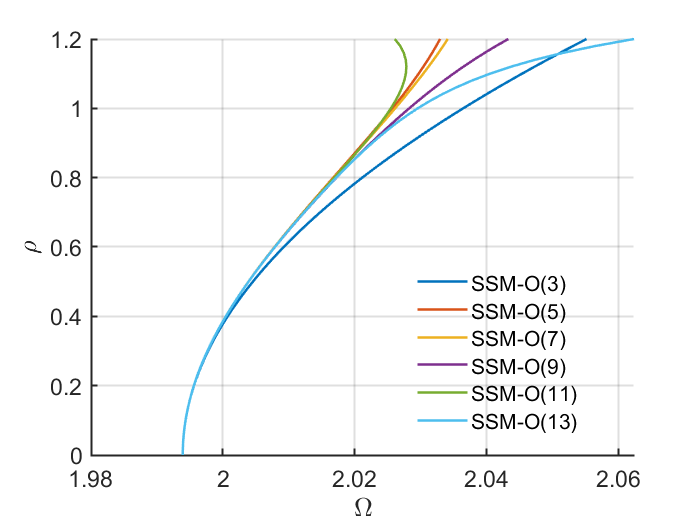

rhosamp = 0:0.02:1.2;
orders = [3 5 7 9 11 13];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

#### visualization of 2D SSM

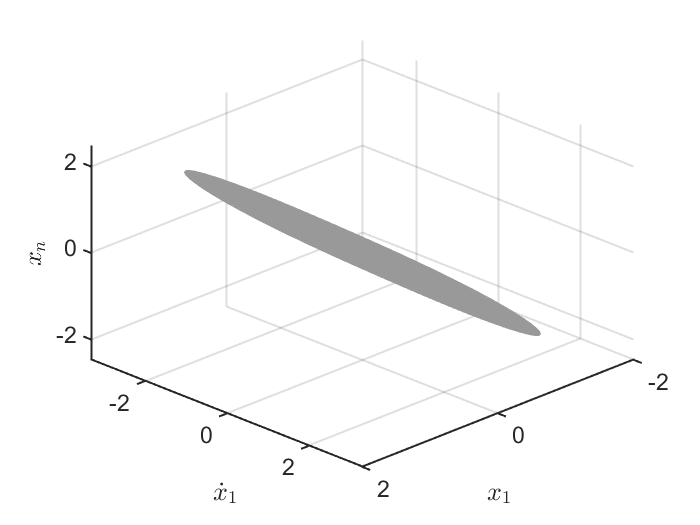

rhosamp = 0:0.04:0.8;
plotdofs = [1 123 120]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_1$','${x}_{n}$'});

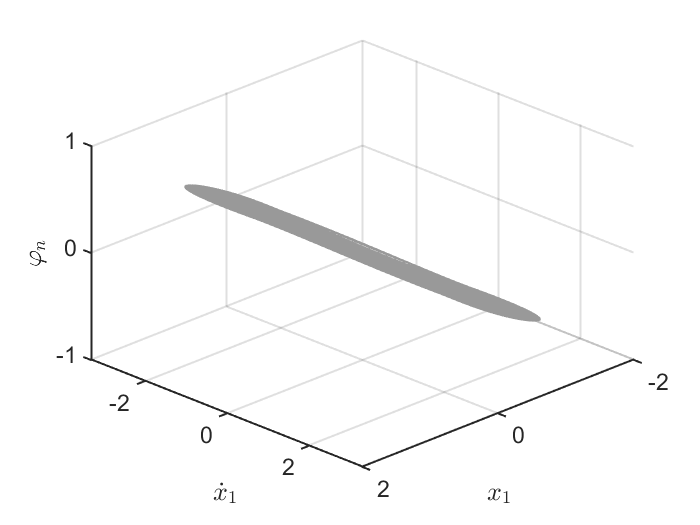

plotdofs = [1 123 122]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_1$','${\varphi}_{n}$'});

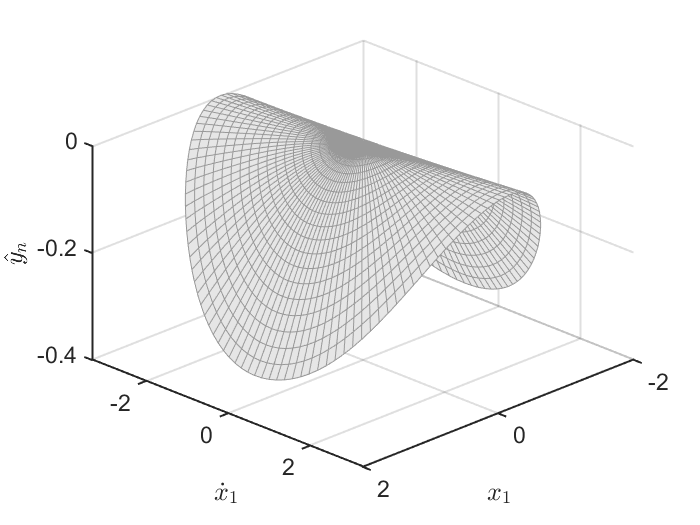

figssmphi = gcf;
plotdofs = [1 123 121]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_1$','${\hat{y}}_{n}$'});

figssm = gcf;

#### Transient response validation

We take an initial condition on SSM and perform forward simulation using both the reduced-order model and the full model

tf = 50;
nsteps = 1000;
q0 = 0.8*exp(1i*3);
q0 = [q0;conj(q0)];
exporder = order;
z0 = reduced_to_full_traj(0,q0,W0(1:exporder));
dofs = [1 120 121 122 123];
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0(1:exporder), R0(1:exporder),...
    tf, nsteps, dofs, [], q0);

Reference solution from forward simulation

options = odeset('RelTol',1e-8,'AbsTol',1e-10);
epf = 0; omega = 2*pi; 
psp = [epf; omega];
% shift of y
ndof  = 2+3*(n-1);
yshift = (0.5+(0:n-2)')*len;
z0(4:3:ndof-1) = z0(4:3:ndof-1)+yshift;
func = @(t,x) pend_chain_ode(t,x,psp,m1,m,c1,c,k1,k,len,n);
[tInt1, zInt1] = ode15s(func, [0 tf], z0(1:2*ndof),options);

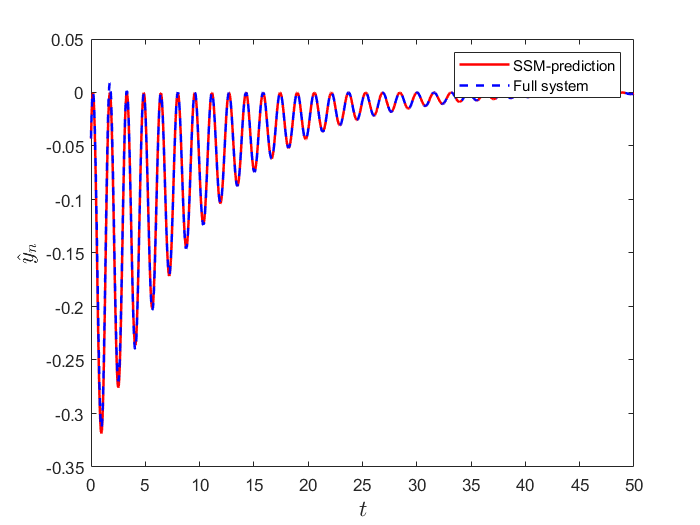

figure;
plot(traj.time,traj.phy(:,3),'r-','LineWidth',1.5); hold on
plot(tInt1,zInt1(:,plotdofs(3))-yshift(end),'b--','LineWidth',1.5);
legend('SSM-prediction','Full system')
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$\hat{y}_{n}$','Interpreter',"latex",'FontSize',14);

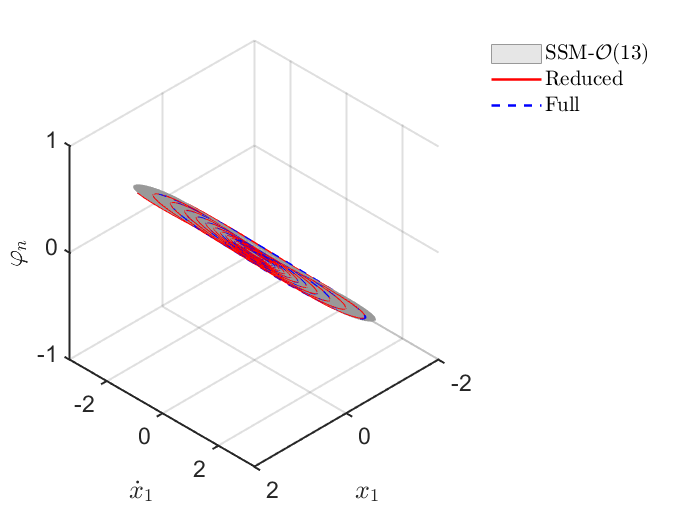


figure(figssmphi); hold on
hold on
plot3(traj.phy(:,1),traj.phy(:,5),traj.phy(:,4),'r-','LineWidth',1.5);
plot3(zInt1(:,plotdofs(1)),zInt1(:,plotdofs(2)),zInt1(:,122),'b--','LineWidth',1.5);
legend('SSM-$\mathcal{O}(13)$','Reduced','Full','interpreter','latex');
legend boxoff

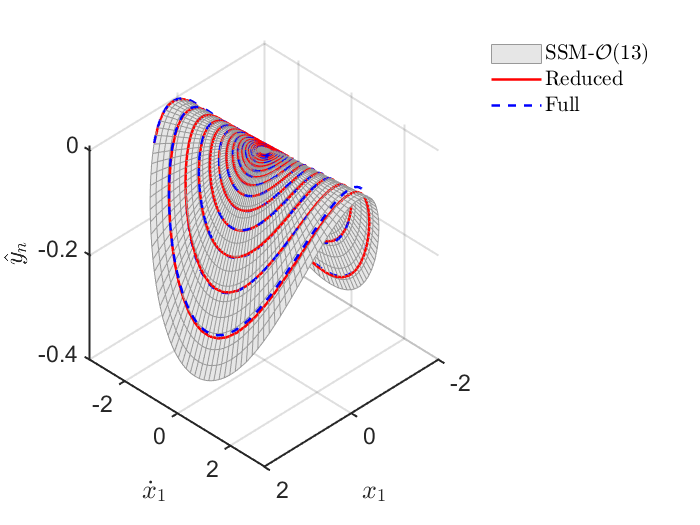


figure(figssm); hold on
hold on
plot3(traj.phy(:,1),traj.phy(:,5),traj.phy(:,3),'r-','LineWidth',1.5);
plot3(zInt1(:,plotdofs(1)),zInt1(:,plotdofs(2)),zInt1(:,plotdofs(3))-yshift(end),'b--','LineWidth',1.5);
legend('SSM-$\mathcal{O}(13)$','Reduced','Full','interpreter','latex');
legend boxoff

#### Backbone curve 

#### SSM prediction

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.67E+00 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.82E+00 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.98E+00 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.26E+00 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.59E+00 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 4.05E+00 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 4.59E+00 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 5.29E+00 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 6.09E+00 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 7.06E+00 MB

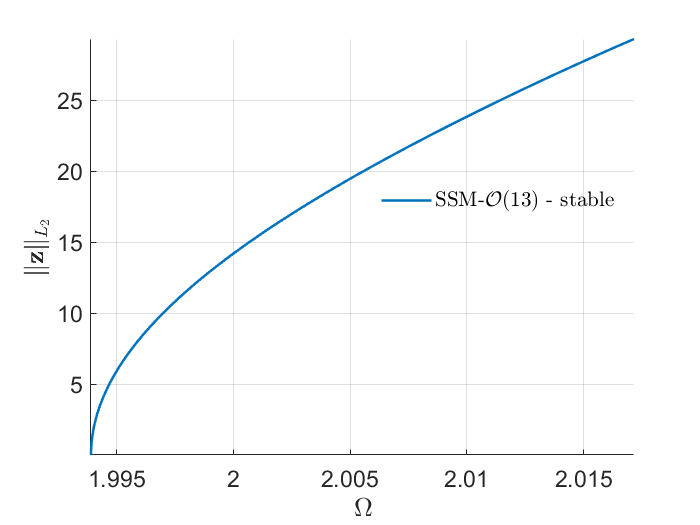

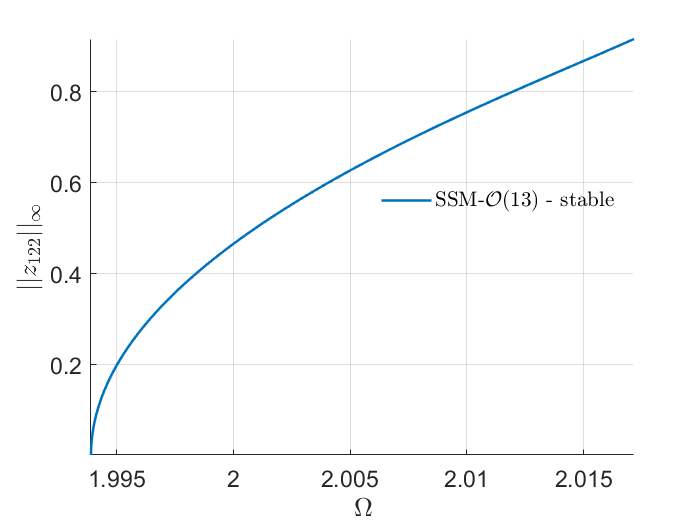

Total time spent on backbone curve computation = 00:00:07


outdof = 2+(n-1)*3;
set(S.FRCOptions,'outDOF',outdof);
freqRange = [1.85 2.1];
rhomax = 0.8;
BB = S.extract_backbone(resonant_modes, freqRange, 13, rhomax);

figbc = gcf;

## Nonautonomous SSM

epsilon = 0.6;
kappas = [1; -1];
coeffs = [Fext Fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### SSM computation

S = SSM(DS);
set(S.FRCOptions,'coordinates','polar')
set(S.Options, 'reltol', 0.5,'notation','multiindex');
outdof = 2+(n-1)*3; %[1 2+(n-1)*3-2 2+(n-1)*3];             % outdof

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.67E+00 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.81E+00 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='freqSubint1.ep': Continue equilibria al

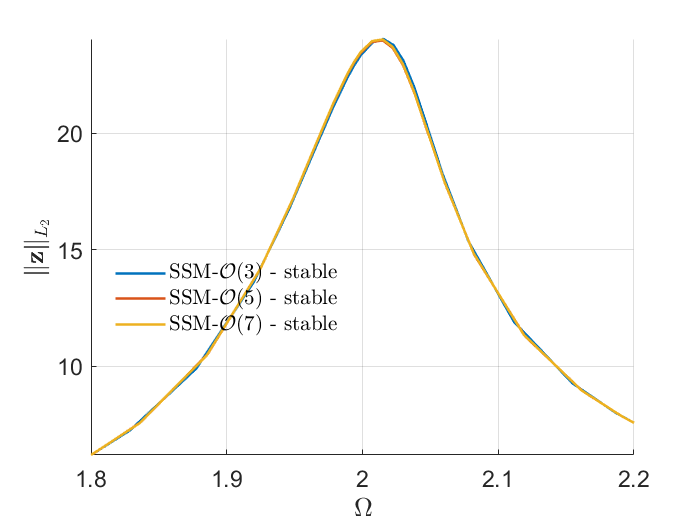

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.67E+00 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.81E+00 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.98E+00 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 3.25E+00 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

set(S.FRCOptions, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.contOptions, 'PtMX', 200, 'h_max', 0.5);               % continuation setting
set(S.FRCOptions,'method','continuation ep','outdof',outdof,'z0',[],'p0',[])
freqRange = [1.8 2.2];
% S.extract_FRC('freq',freqRange,[5 7 9 15 17 21 23]);
S.extract_FRC('freq',freqRange,[3 5 7]);

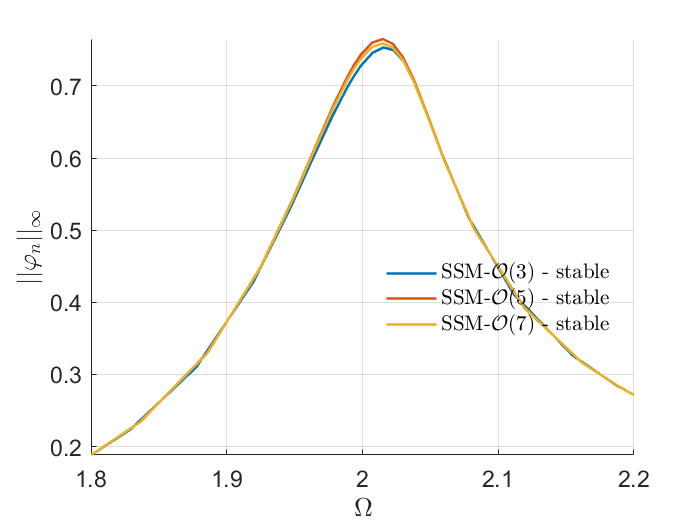

ylabel('$||\varphi_n||_\infty$','Interpreter','latex','FontSize',14);

figssm = gcf;

### Validation

Plot results

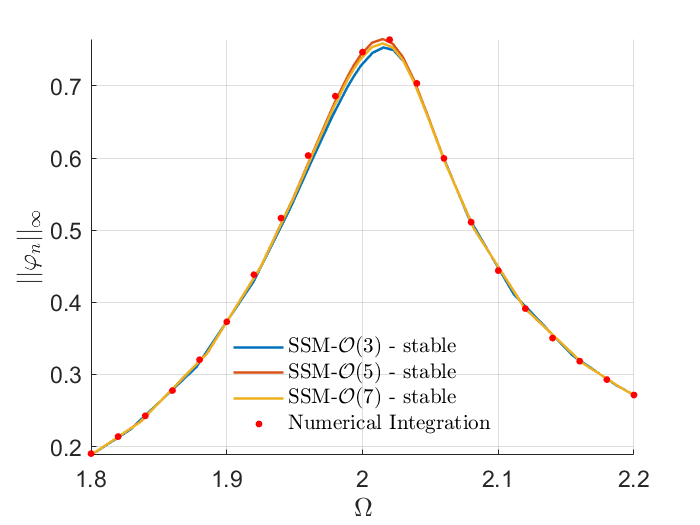

figure(figssm); hold on
fw = load('fw0point6.mat');
plot(fw.omsamp,fw.amp,'r.','MarkerSize',14,'DisplayName','Numerical Integration');

Add FRC from linear analysis

set(DS.Options,'outDOF',outdof);
omegas = 1.8:0.01:2.2;
[response,Znorm,Aout] = linear_response(DS,omegas);
plot(omegas,Aout,'k:','LineWidth',1.5,'DisplayName','Linear');

Add backbone curve and the linear analysis result

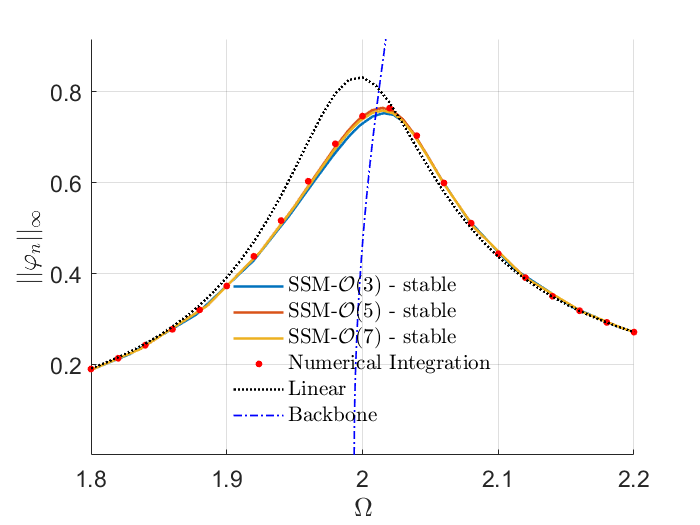

plot([BB.Omega],[BB.Aout],'b-.','LineWidth',1.0,'DisplayName','Backbone');